# Path Planning for Drone

Move 4 ft x 4 ft drone using RRT Planner

Load map of house 

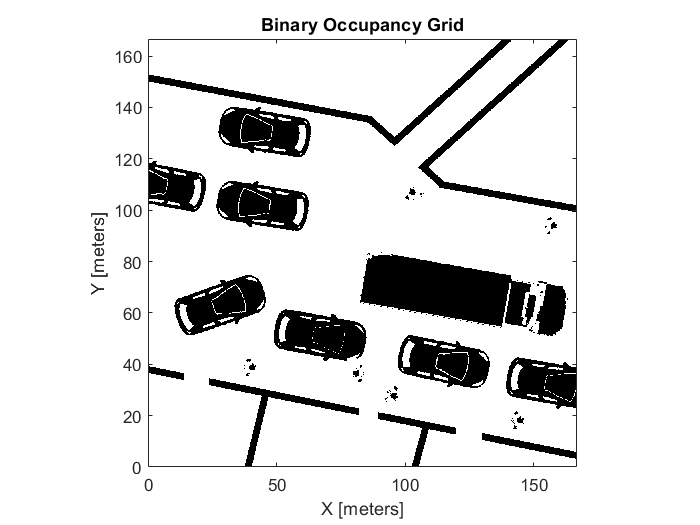

clear all
close all

% load image and create Occupancy map from image
image = imread('city_map.png');
grayimage = rgb2gray(image);
bwimage = grayimage < 0.5;
grid = binaryOccupancyMap(bwimage,9);
show(grid)

Create costmap using vehicleCostmap function from toolbox

costmap = vehicleCostmap(grid)

costmap =   vehicleCostmap with properties:

        FreeThreshold: 0.2000
    OccupiedThreshold: 0.6500
     CollisionChecker: [1×1 driving.costmap.InflationCollisionChecker]
             CellSize: 0.1111
              MapSize: [1500 1500]
            MapExtent: [0 166.6667 0 166.6667]


Modify dimensions of drone and parameters of collision checker.  Drone is 4 ft x 4 ft.  

One circle of radius 2.5 ft at the center of the drone will be used to check for collisions.

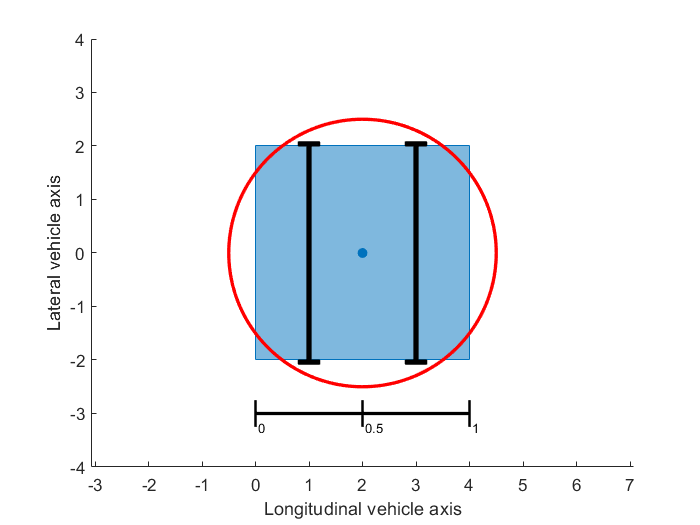


capsuledims = vehicleDimensions(4,4, 'FrontOverhang',1,'RearOverhang',1); 
numCircles = 1;
inflationRadius = 2.5;
ccConfig = inflationCollisionChecker(capsuledims, numCircles,'InflationRadius',inflationRadius);
plot(ccConfig)

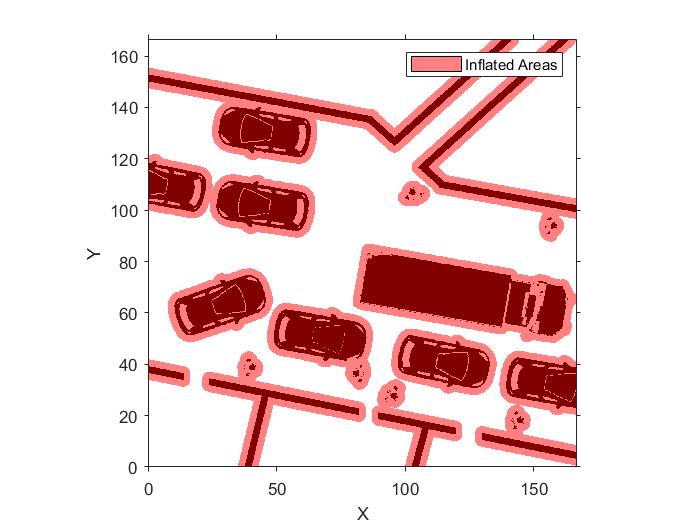


costmap.CollisionChecker = ccConfig;

figure
plot(costmap)

Run the path planner and plot on the map

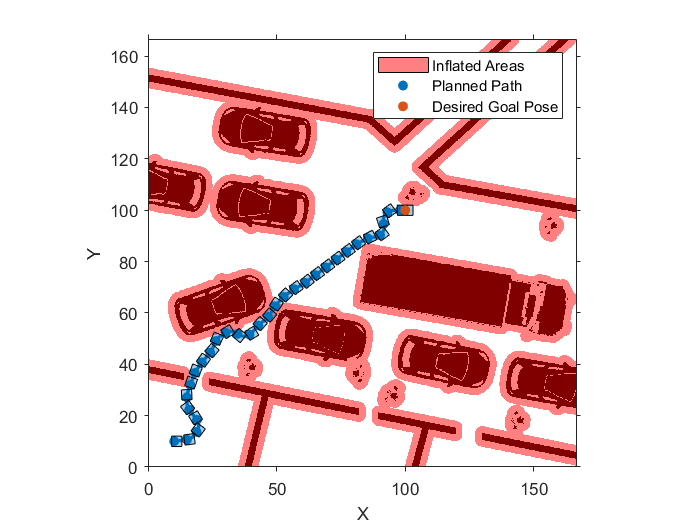

%Set the start and goal states.
start = [10,10,0];
goal = [100,100,0];

planner = pathPlannerRRT(costmap);
refPath = plan(planner,start,goal);

plot(planner)
hold on